## Raised Cosine

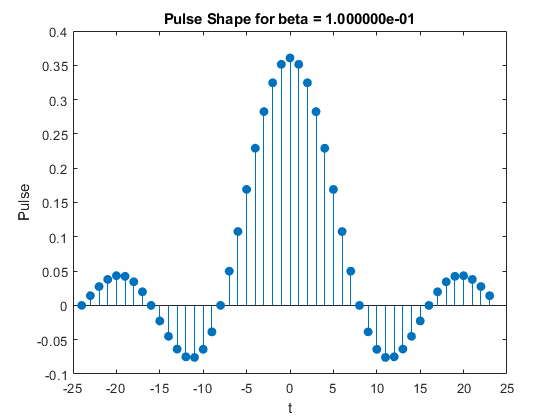

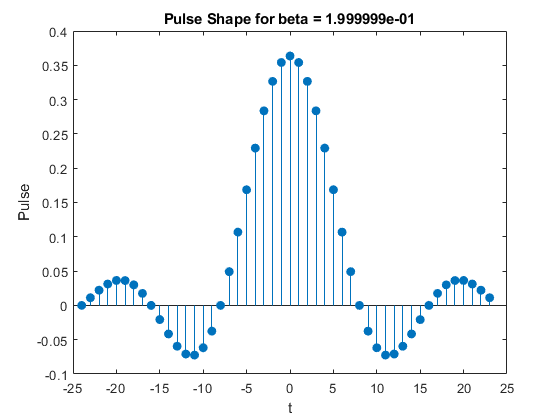

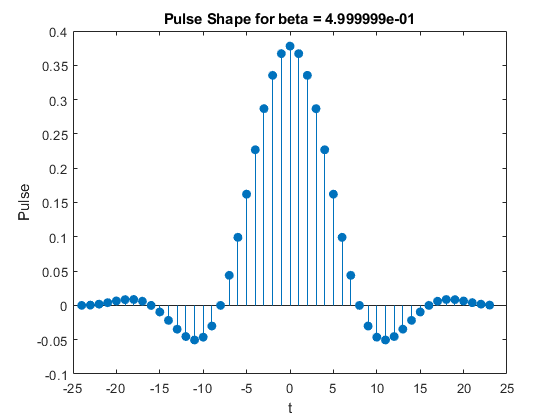

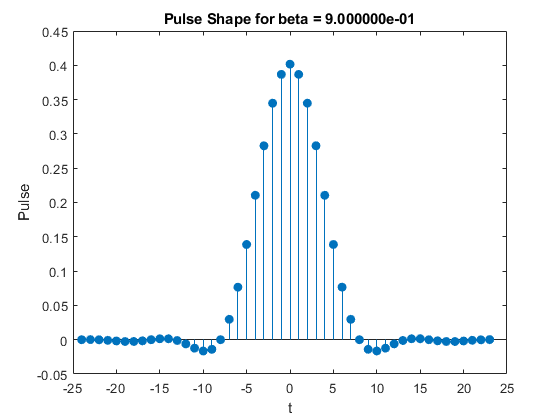

clear all
fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
span_in_symbl = 6;
betas = [0.1, 0.1999999, 0.4999999, 0.9];
for i=1:length(betas)
    figure
    [p, t] = pulse_shape('raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    stem(t,p,'filled')
    title(sprintf('Pulse Shape for beta = %d', betas(i)))
    xlabel('t')
    ylabel('Pulse')
end

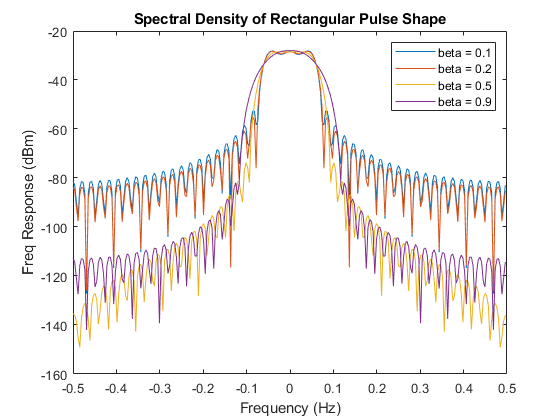

figure
for i=1:length(betas)
    [p, t] = pulse_shape('raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    [s, freq] = spectral_dens(p, fs, n_fft);
    plot(freq, s)
    title('Spectral Density of Rectangular Pulse Shape')
    xlabel('Frequency (Hz)')
    ylabel('Freq Response (dBm)')
    hold on
end
legend 'beta = 0.1' 'beta = 0.2' 'beta = 0.5' 'beta = 0.9'

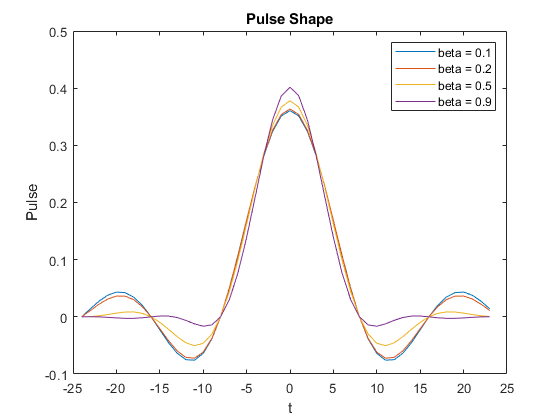

figure
for i=1:length(betas)
    [p, t] = pulse_shape('raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    plot(t,p)
    title('Pulse Shape')
    xlabel('t')
    ylabel('Pulse')
    hold on
end
legend 'beta = 0.1' 'beta = 0.2' 'beta = 0.5' 'beta = 0.9'

## Root Raised Cosine

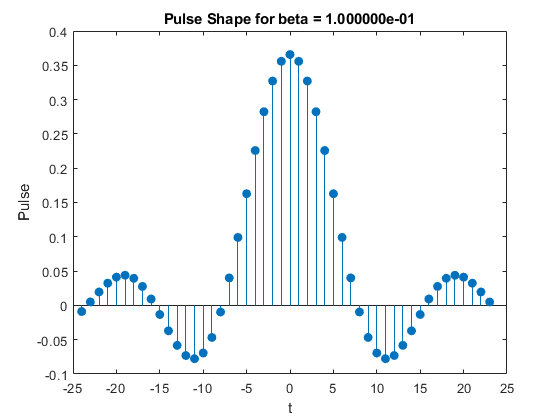

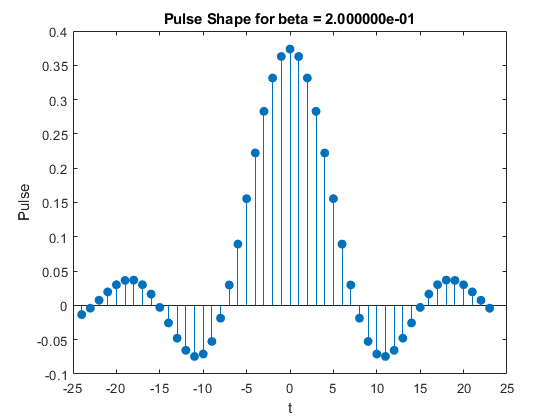

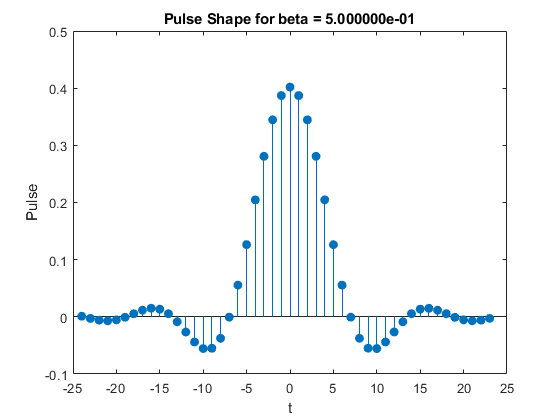

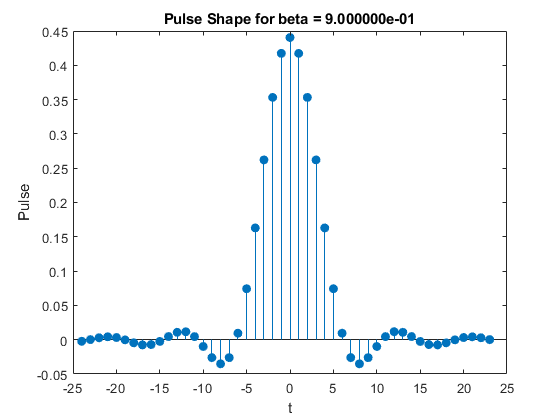

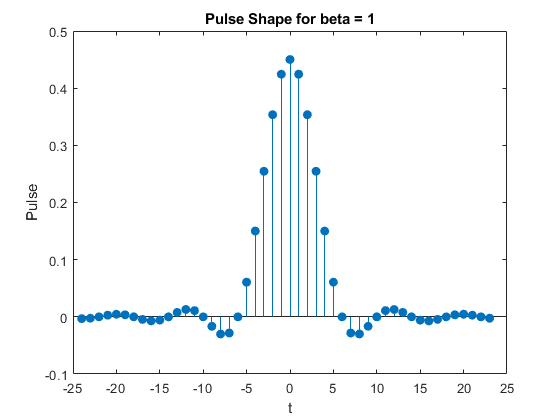

clear all
fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
span_in_symbl = 6;
betas = [0.1, 0.2, 0.5, 0.9, 1];
for i=1:length(betas)
    figure
    [p, t] = pulse_shape('root_raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    stem(t,p,'filled')
    title(sprintf('Pulse Shape for beta = %d', betas(i)))
    xlabel('t')
    ylabel('Pulse')
end

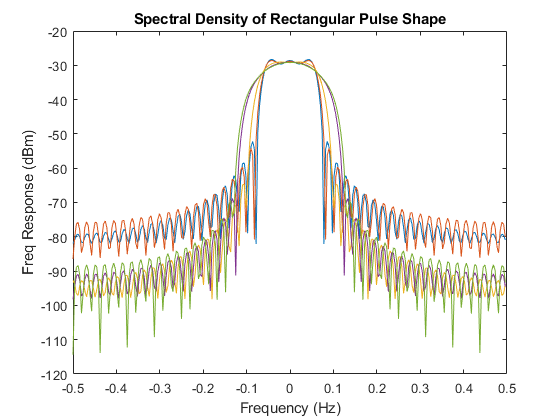

figure
for i=1:length(betas)
    [p, t] = pulse_shape('root_raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    [s, freq] = spectral_dens(p, fs, n_fft);
    plot(freq, s)
    title('Spectral Density of Rectangular Pulse Shape')
    xlabel('Frequency (Hz)')
    ylabel('Freq Response (dBm)')
    hold on
end

'beta = 0.9'

ans = 'beta = 0.9'

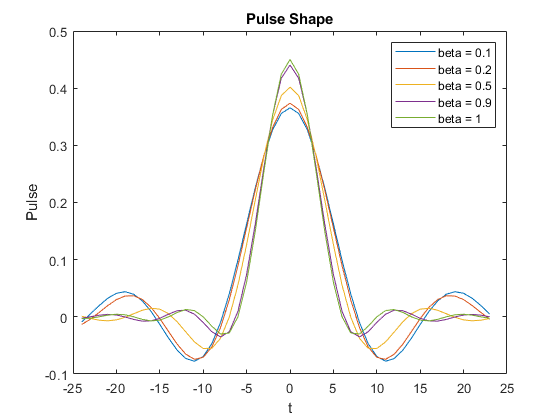

figure
for i=1:length(betas)
    [p, t] = pulse_shape('root_raised_cosine', fs, smpl_per_symbl, betas(i), span_in_symbl);
    plot(t,p)
    title('Pulse Shape')
    xlabel('t')
    ylabel('Pulse')
    hold on
end
legend 'beta = 0.1' 'beta = 0.2' 'beta = 0.5' 'beta = 0.9' 'beta = 1'

## Gaussian

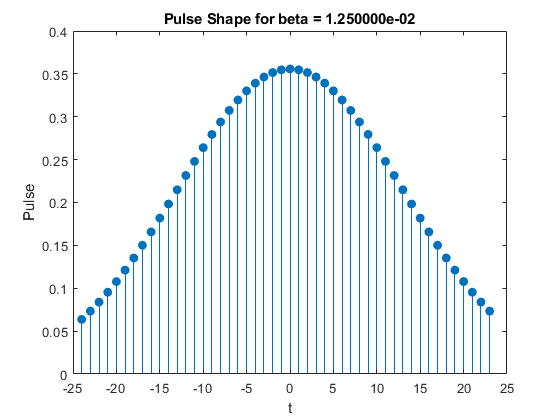

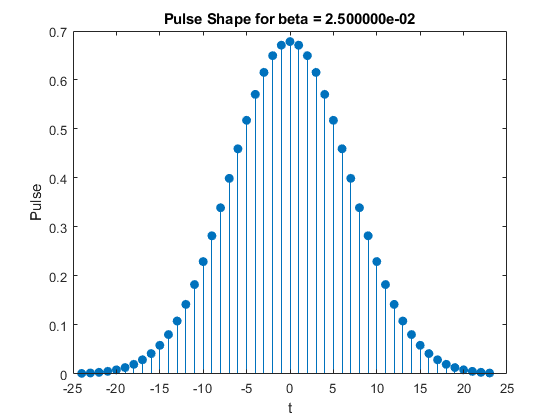

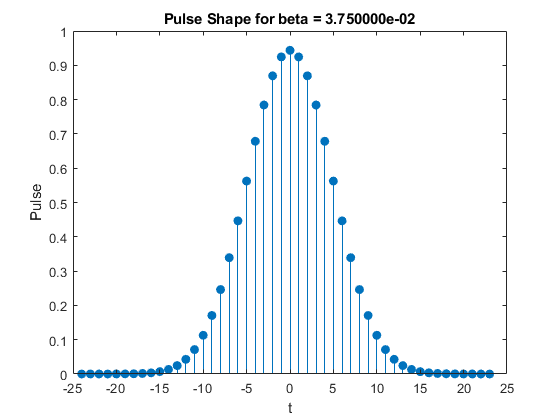

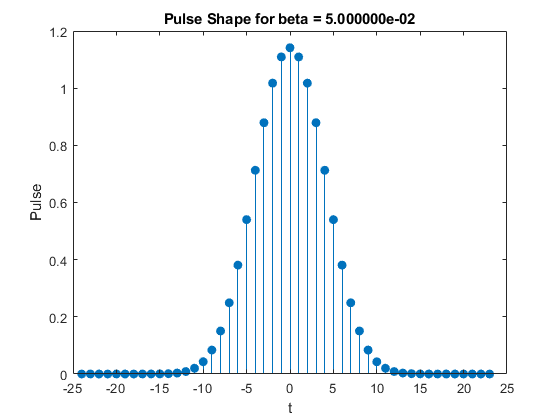

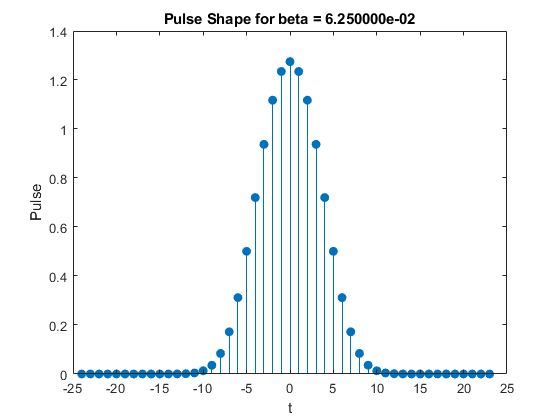

clear all
fs = 1;
smpl_per_symbl = 8;
Ts = smpl_per_symbl/fs;
n_fft = 256;
span_in_symbl = 6;
betas = [0.1, 0.2, 0.3, 0.4, 0.5] / Ts;
for i=1:length(betas)
    figure
    [p, t] = pulse_shape('gaussian', fs, smpl_per_symbl, betas(i), span_in_symbl);
    stem(t,p,'filled')
    title(sprintf('Pulse Shape for beta = %d', betas(i)))
    xlabel('t')
    ylabel('Pulse')
end

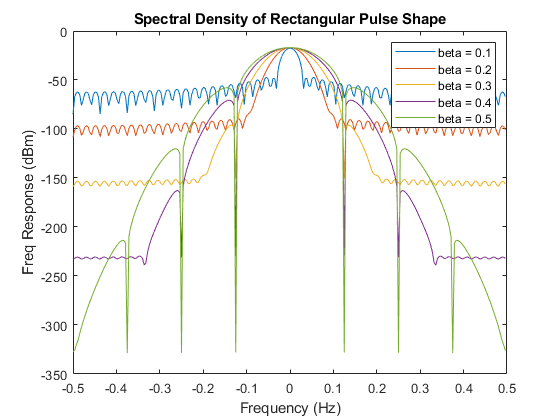

figure
for i=1:length(betas)
    [p, t] = pulse_shape('gaussian', fs, smpl_per_symbl, betas(i), span_in_symbl);
    [s, freq] = spectral_dens(p, fs, n_fft);
    plot(freq, s)
    title('Spectral Density of Rectangular Pulse Shape')
    xlabel('Frequency (Hz)')
    ylabel('Freq Response (dBm)')
    hold on
end
legend 'beta = 0.1' 'beta = 0.2' 'beta = 0.3' 'beta = 0.4' 'beta = 0.5'

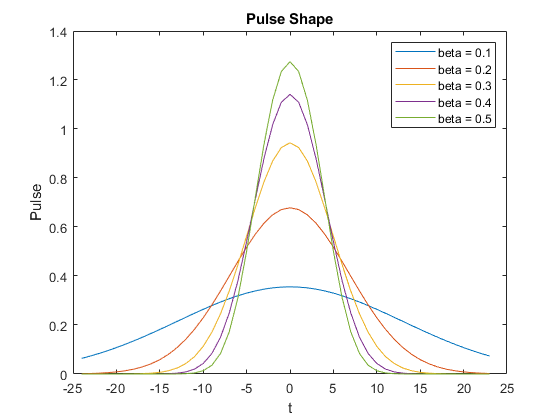

figure
for i=1:length(betas)
    [p, t] = pulse_shape('gaussian', fs, smpl_per_symbl, betas(i), span_in_symbl);
    plot(t,p)
    title('Pulse Shape')
    xlabel('t')
    ylabel('Pulse')
    hold on
end
legend 'beta = 0.1' 'beta = 0.2' 'beta = 0.3' 'beta = 0.4' 'beta = 0.5'


$$$P_{e}=2\left(\frac{M-1}{M}\right) Q\left[\sqrt{\frac{6 \log _{2}(M)}{\left(M^{2}-1\right) N_{0}} E_{b a v}}\right]$$$



$$$P_{e b}=\frac{P e}{\log _{2}(M)}$
$$


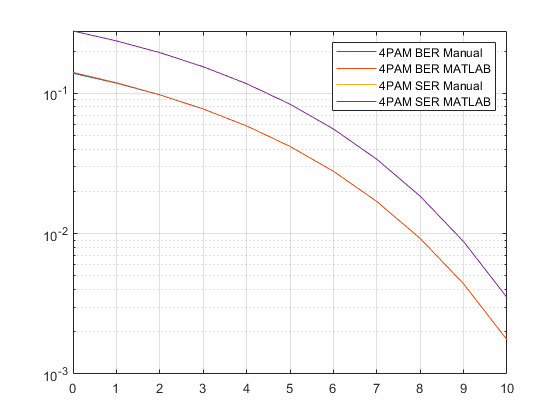

figure
M = 4;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);
berPAM = ((2 * (M - 1) / M) * qfunc(sqrt((6 * log2(M) * EbNo)/(M^2 - 1)))) / (log2(M));
serPAM = ((2 * (M - 1) / M) * qfunc(sqrt((6 * log2(M) * EbNo)/(M^2 - 1))));
[berPAM_matlab,serPAM_matlab] = berawgn(EbNo_dB,'pam',4);
semilogy(EbNo_dB,[berPAM, berPAM_matlab, serPAM, serPAM_matlab])
legend('4PAM BER Manual','4PAM BER MATLAB', '4PAM SER Manual', '4PAM SER MATLAB')
grid on


$$$P_{e s}=2 Q\left[\sqrt{\frac{2 \log _{2}(M) E_{b}}{N_{0}}} \sin (\pi / M)\right], \quad P_{e b}=\frac{P_{e s}}{\log _{2}(M)}$$$


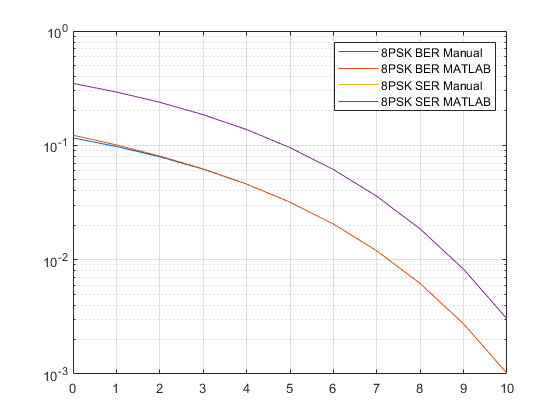

figure
M = 8;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);
berPSK =  (2 *  qfunc(sqrt((2 * log2(M) * EbNo)) * sin(pi/M)) / (log2(M)));
serPSK =  2 *  qfunc(sqrt((2 * log2(M) * EbNo)) * sin(pi/M));
[berPSK_matlab, serPSK_matlab] = berawgn(EbNo_dB,'psk',8,'nondiff');
semilogy(EbNo_dB,[berPSK, berPSK_matlab, serPSK, serPSK_matlab])
legend('8PSK BER Manual','8PSK BER MATLAB', '8PSK SER Manual', '8PSK SER MATLAB')
grid on

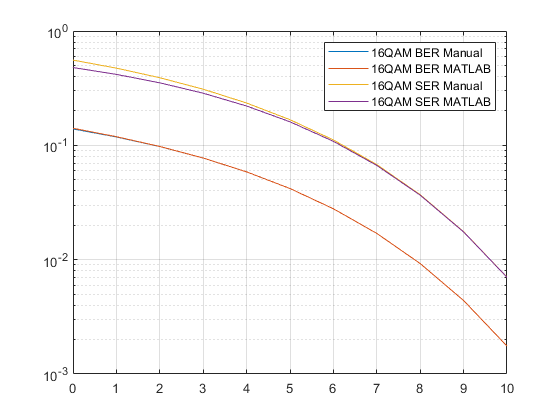

figure
M = 16;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);
berQAM = (sqrt(M) - 1) / sqrt(M) *4 * qfunc(sqrt((3 * log2(M) * EbNo / (M - 1)))) / (log2(M));
serQAM = (sqrt(M) - 1) / sqrt(M) *4 * qfunc(sqrt((3 * log2(M) * EbNo / (M - 1))));
[berQAM_matlab, serQAM_matlab] = berawgn(EbNo_dB,'qam',16);
semilogy(EbNo_dB,[berQAM, berQAM_matlab, serQAM, serQAM_matlab])
legend('16QAM BER Manual','16QAM BER MATLAB', '16QAM SER Manual', '16QAM SER MATLAB')
grid on

A little difference can be seen because of approximation (ignoring Q^2)

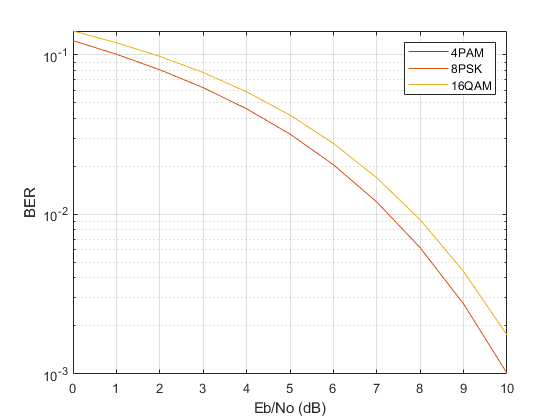

EbNo = (0:10)';
M = 4;
berPAM = berawgn(EbNo,'pam',4);
berPSK = berawgn(EbNo,'psk',8,'nondiff');
berQAM = berawgn(EbNo,'qam',16);
figure
semilogy(EbNo,[berPAM berPSK berQAM])
xlabel('Eb/No (dB)')
ylabel('BER')
legend('4PAM','8PSK','16QAM')
grid